# Data Augmentation para la Situación Problema

Los problemas manejados por aprendizaje automático se basan el manejo de grandes volúmenes de datos para lograr que el modelo generalice de mejor forma. Sin embargo, cuando el tamaño de la base de datos es reducida, los resultados del modelo no son los mejores. Una forma de reducir este problema, es aumentar el tamaño de los datos incluyendo variaciones probabilistícas basadas en los datos existentes. Es aquí donde entra en acción la función audioDataAugmenter. Más información del uso de esta función se puede encontrar en el siguiente enlace: [https://la.mathworks.com/help/audio/ref/audiodataaugmenter.html](https://la.mathworks.com/help/audio/ref/audiodataaugmenter.html)

A continuación, se expondrán los detalles de uso de la función audioDataAugmenter en uno de los cuatro posibles modos de operación. 

## Operaciones

Las operaciones que la función audioDataAugmenter usa para incrementar el tamaño de la base de datos se listan a continuación.

### Stretch Time

Esta operación permite hacer la señal de audio más rápida o más lenta para permitirle al modelo que considere variaciones en la velocidad de la voz para poderla clasificar correctamente.

### Shift Pitch

El pitch es la armónica o frecuencia fundamental que caracteriza a la voz en una señal de audio y esta operación permite modificar dicha frecuencia desplazándola hacia frecuencias más bajas o más altas. Dado que el pitch es una característica importante en el modelo de aprendizaje automático, no va a ser modificada por la función audioDataAugmenter.

### Control Volume

Esta operación modifica aleatoriamente el volumen de la señal de audio para permitirle al modelo de aprendizaje automático que pueda clasificar a pesar del volumen con el que los audio fueron grabados.

Esta operación permite agregar ruido blanco de fondo o modificar la relación señal a ruido de las señales de audio para permitirle al modelo que pueda clasificar a pesar de la presencia de ruido en la señal.

### Shift Time

Esta operación permite adelantar o retrasar una señal de audio por una cierta candidad de segundos con la finalidad de que el modelo pueda llevar a cabo la clasificación de manera independiente a la ubicación en tiempo de la señal de voz en el audio.

## Modos de Operación

Para aplicar las operaciones discutidas arriba, la función audioDataAugmenter soporta los modos independiente y secuencial. Si se opta por el modo independiente, las operaciones son aplicadas de manera independiente a la señal de audio y sumados todos los resultados al final. Si se opta por el modo secuencial, cada una de las operaciones son aplicadas en un cierto orden, una detrás de la otra, con lo cual, las operaciones se van acumulando. Así mismo, la función soporta los modos aleatorio (random) y específico. En modo específico, por cada operación, se debe indicar el valor de las variaciones que debe sufrir el audio original, mientras que en el modo aleatorio, de manera aleatoria se aplican las variaciones de cada operación a la señal de audio original. En este script, sólo el modo aleatorio secuencia será demostrado, el cual es representado por la imagen mostrada abajo.

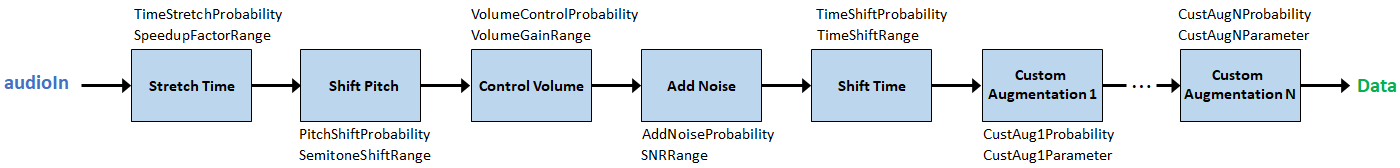

## Ejemplo

A continuación se muestra un ejemplo del uso de audioDataAugmenter en modo secuencial aleatorio, sin la operación de shift pitch y con la generación de 10 aumentaciones. Para fines de ejemplo, se reproduce uno de los 10 audios generados por la función.

% Directorios de entrada y salida
inputFolder = "C:\Users\alfre\Music\Audios_reto\Mariam";
outputFolder = "C:\Users\alfre\Music\Audios_Reto2\Mariam";

% Obtener la lista de archivos WAV en la carpeta de entrada
audioFiles = dir(fullfile(inputFolder, '*.wav'));

% Configuración del aumentador
augmenter = audioDataAugmenter( ...
    "AugmentationMode","sequential", ...
    'AugmentationParameterSource','random', ...
    "NumAugmentations",10, ...
    "TimeStretchProbability",0.8, ...
    "SpeedupFactorRange",[1.2,1.3], ...
    "PitchShiftProbability",0, ...
    "VolumeControlProbability",0.8, ...
    "VolumeGainRange",[-5,5], ...
    "AddNoiseProbability",0.5, ...
    "SNRRange",[0,20], ...
    "TimeShiftProbability",0.8, ...
    "TimeShiftRange",[-200e-3,200e-3]);

% Procesar cada archivo de audio en la carpeta de entrada
for i = 1:length(audioFiles)
    % Leer el archivo de audio
    audioFileName = audioFiles(i).name;
    [audioIn, fs] = audioread(fullfile(inputFolder, audioFileName));
    
    % Generar las variaciones
    data = augment(augmenter, audioIn, fs);
    
    % Guardar cada variación en la carpeta de salida
    for j = 1:10
        augmentation = data.Audio{j};
        
        % Normalizar la señal de audio para evitar clipping
        augmentation = augmentation / max(abs(augmentation));
        
        [~, baseFileName, ~] = fileparts(audioFileName);
        outputFileName = sprintf('%s_aug%d.wav', baseFileName, j);
        audiowrite(fullfile(outputFolder, outputFileName), augmentation, fs);
    end
end

disp('Procesamiento completo. Archivos guardados en la carpeta de salida.');

Procesamiento completo. Archivos guardados en la carpeta de salida.


Es importante que, después de hacer la aumentación de datos, se verifique que las señales de audio suenan de manera adecuada en MATLAB. 

## Conclusiones

Se ha mostrado uno de los cuatro modos de operación de la función audioDataAugmenter para hacer crecer la base de datos de señales de audio y así mejorar la tarea de clasificación del modelo de aprendizaje automático que se usará como parte de la solución de la situación problema. En el código ejemplo, se muestran sólo algunos valores y no se exploran sus efectos en los audios generados. Estos valores deben ser revisados para mejorar el aprendizaje en el modelo.